# Reference Model

zeta = 0.95;
omega = 1;

s = tf('s');
trf = 1/(s^2 + 2*zeta*omega*s + omega^2);

ss_model_ref = tf2ss(trf.Numerator{1,1}, trf.Denominator{1,1});

A = [0 1; -1 -1.9]

A =          0    1.0000
   -1.0000   -1.9000


B = [0; 1];
C = [1, 0;
     0, 1];
D = zeros(2,1);

state_model_full = ss(A, B, C, D)

state_model_full =
 
  A = 
         x1    x2
   x1     0     1
   x2    -1  -1.9
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.


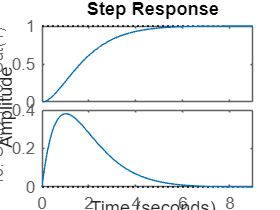

step(state_model_full)

Q = 0.5.*eye(2);
P = lyap(A', Q);